## 1) Correlazione ponderata

Il file regioni.xlsx contiene per ciascuna regione Italiana    

TassoPassaggio=Tasso di passaggio all'Università: immatricolati per 100 diplomati di scuola secondaria di secondo grado dell'anno scolastico precedente;

TassoIscrizione=Tasso di iscrizione all'Università: iscritti all'Università (in qualunque sede) residenti in una certa regione per 100 giovani di 19-25 anni residenti nella stessa regione;

 IscrittiFuoriRegione=Iscritti in sedi universitarie ubicate fuori dalla regione di residenza per 100 iscritti (sono esclusi i cittadini stranieri e gli italiani residenti all'estero);

Residenti=Popolazione residente.

Osservazione: I primi tre indicatori possono ritenersi aspetti diversi della  propensione agli studi universitari in ciascuna regione d'Italia, per cui risulta interessante misurare la relazione esistente tra essi, tramite il calcolo del coeffiente di correlazione lineare. Dato che siamo in presenza di una seria territoriale multipla, appare ragionevole nel calcolo dei diversi indici statistici tenere conto della differente importanza delle regioni.

Mostrare tramite GUI tutti i passaggi necessari per calcolare la correlazione tra le variabili TassoPassaggio  e TassoIscrizione. 

Calcolare la matrice dei coefficienti di correlazione nei 3 diversi modi che seguono:

- Tramite la matrice di varianze e covarianze (v. equazione 6.9 del testo).

- Tramite la matrice degli scostamenti standardizzati. Verificare che le medie e le varianze (oppure le std) delle colonne della matrice Z sono 0 e 1.

- Tramite doppio ciclo for.

Testare l'ipotesi che il vero coefficiente di correlazione sia uguale a 0 nell'universo per ogni coppia di variabili. Calcolare i p-values del test. Mostrare la matrice di correlazione e dei p-values del test di assenza di correlazione in formato table. Commentare i risultati ottenuti

OSSERVAZIONE: questo esercizio è stato estratto dalle pagine 238-239 del libro di Statistica Introduzione all'analisi dei dati statistici (2019) Milioli, Riani e Zani, Pitagore Editore, 

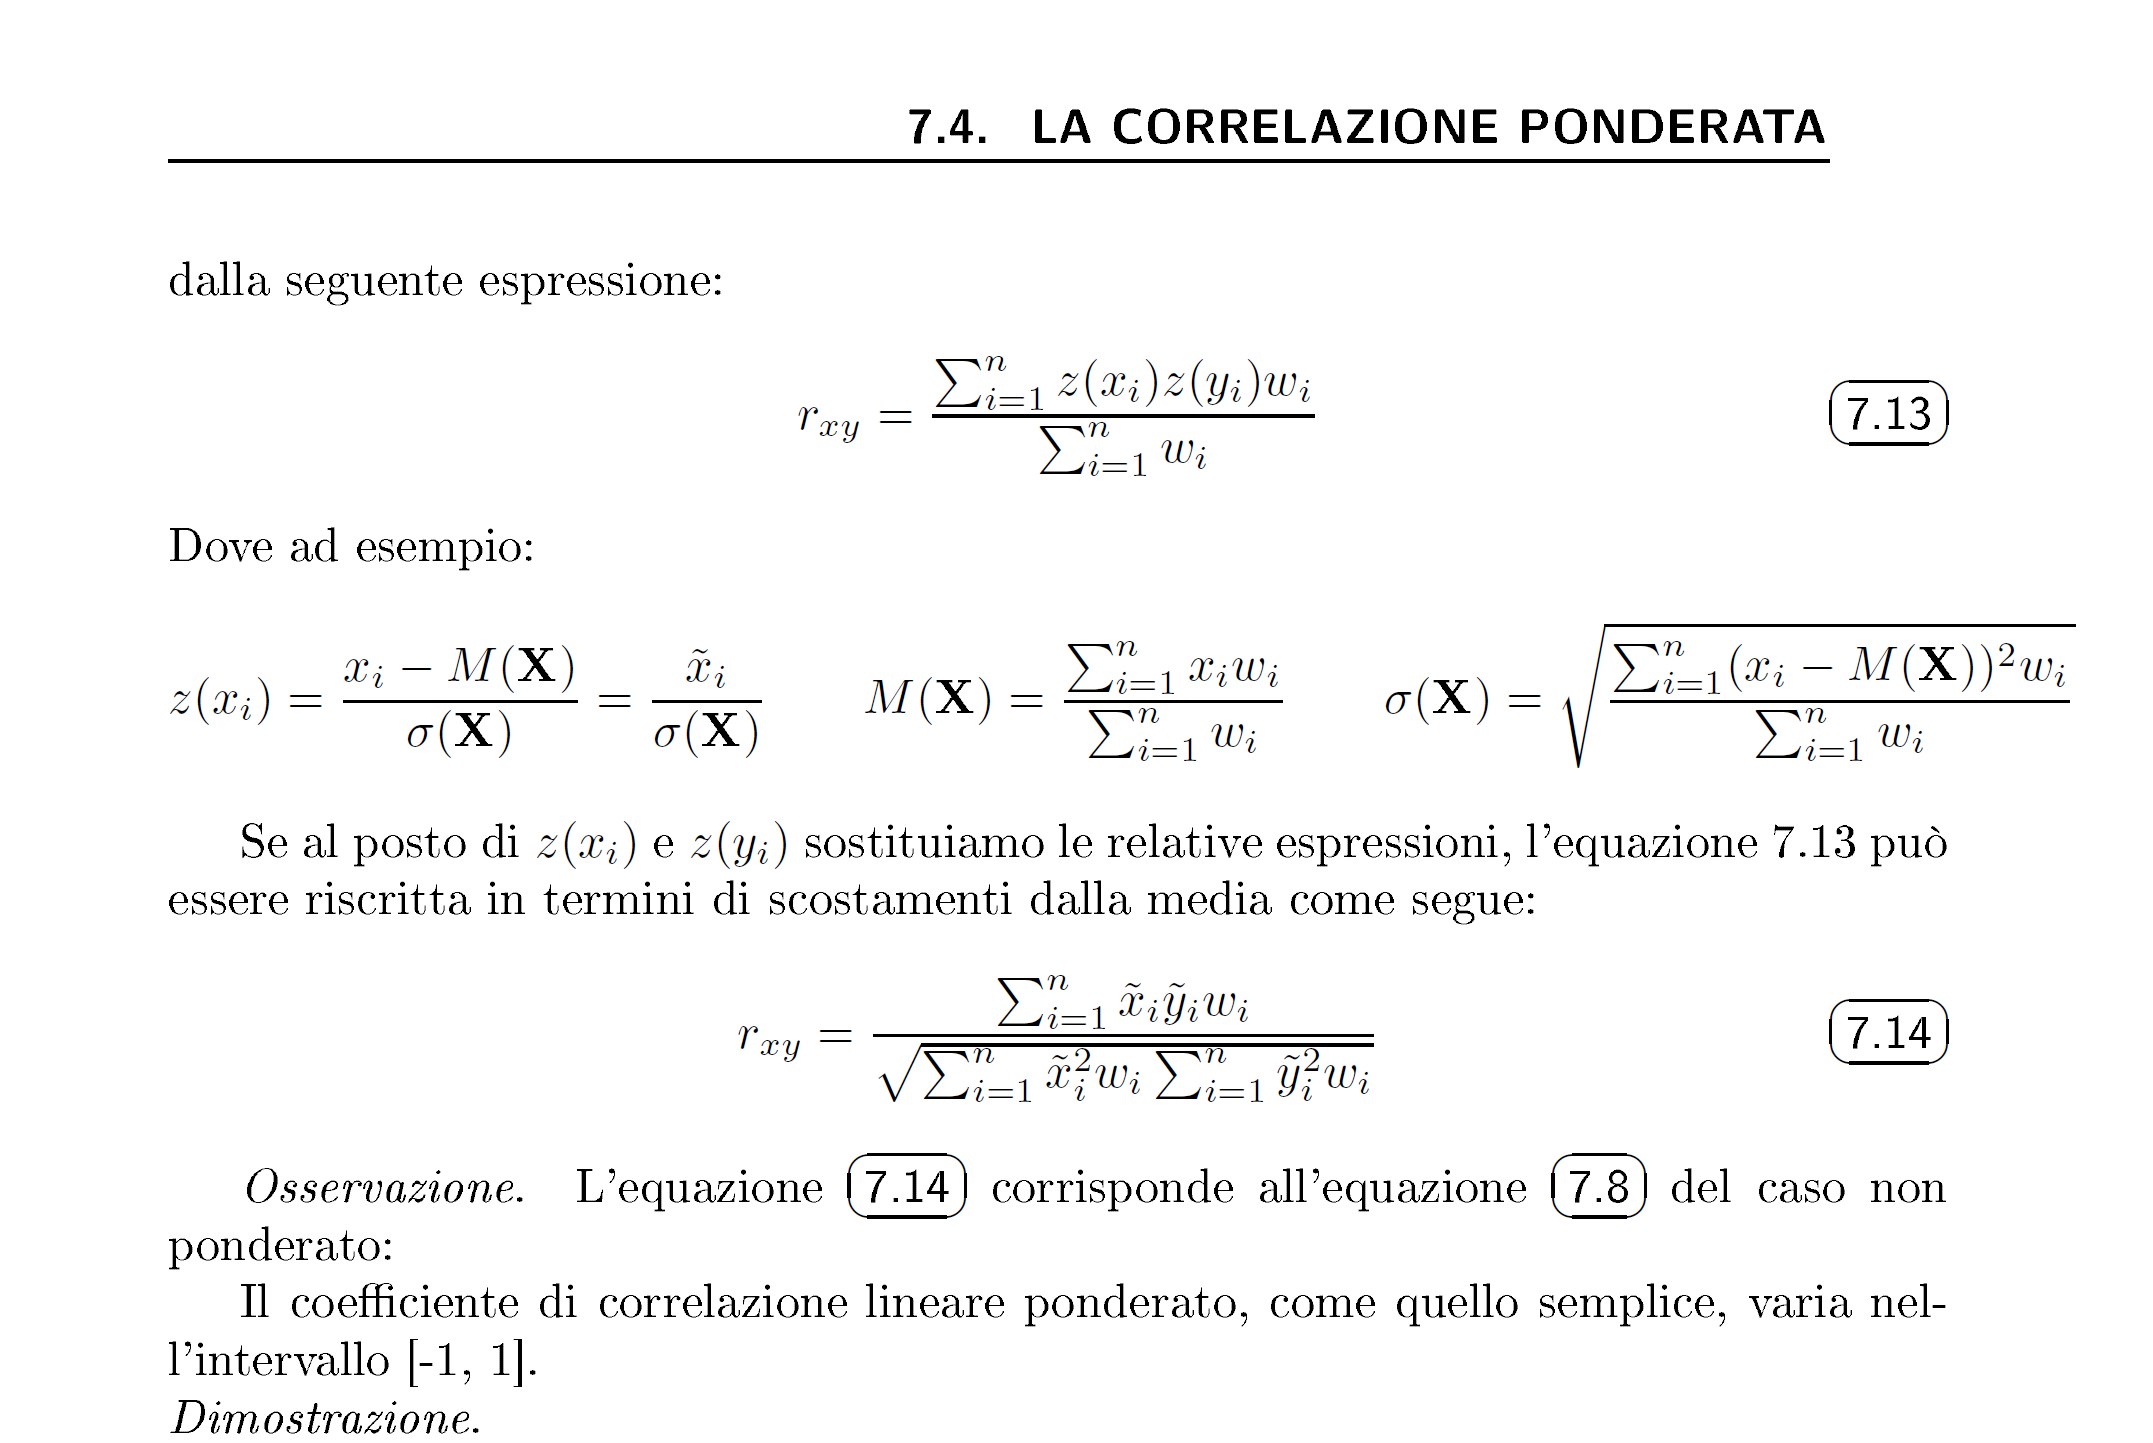

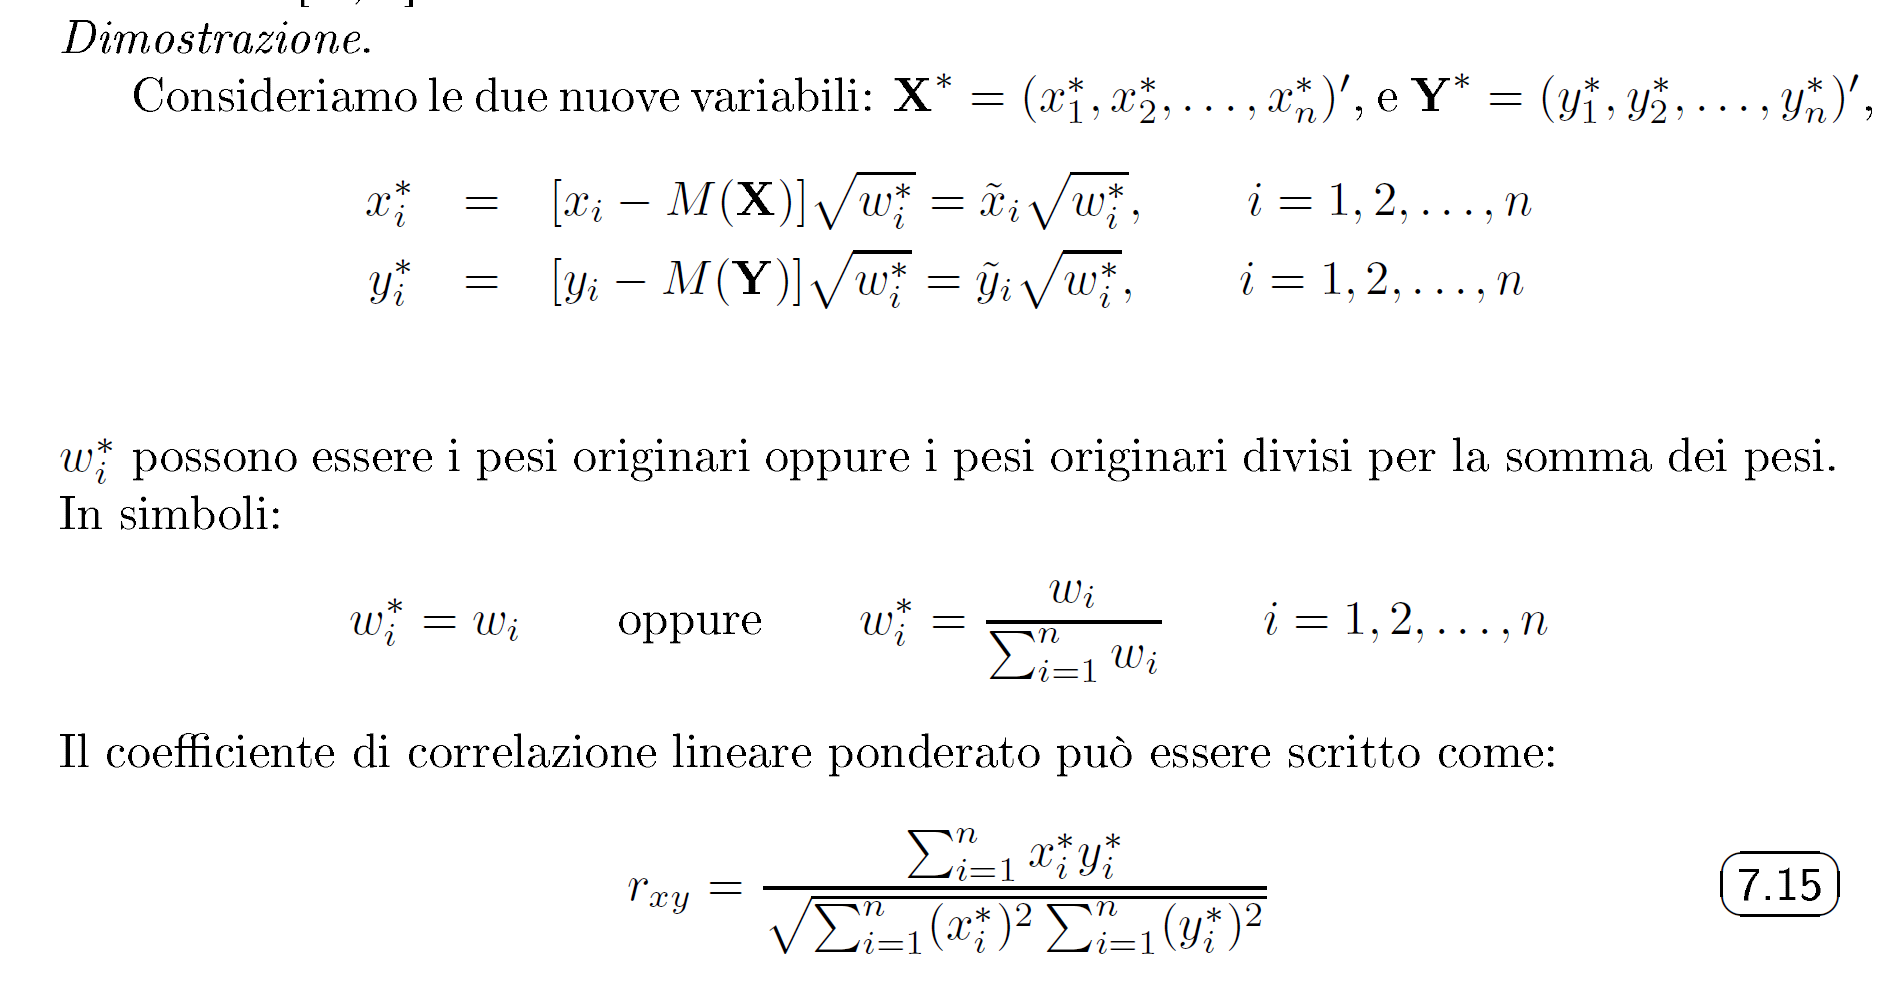

## 2) Matrice di correlazione

Caricare in memoria il file head.mat di FSDA toolbox. Per la descrizione di questo dataset si veda l'Esercizio 8.5 del testo oppure la pagina [Flexible Statistics and Data Analysis Toolbox Functions - - By Category (unipr.it)](http://rosa.unipr.it/FSDA/datasets_mv.html). Calcolare e commentare la matrice di correlazione delle 6 variabili. 

Verificare l'ipotesi di assenza di correlazione per ogni coppia di variabili. Calcolare e commentare i relativi p-values. Mostare la matrici di correlazione e quella dei relativi p-values in formato table. Utilizzare come nomi delle variabili nelle due tables la parola che segue l'ultimo underscore. Ad esempio, se nella table originaria head una variabile si chiama length_tragion_nasion si deve estrarre la parola nasion. Mostrare l'output utilizzando solo due cifre decimali.

clear % cancella tutte le variabili presenti in memoria



## 3) Il significato del *p*-value

In un campione bivariato composto da 7 osservazioni è stato trovato un valore del coefficiente di correlazione lineare uguale -0.65. Se le due variabili sono incorralte nell'universo qual è la probabilità di ottenere nel campione un valore in modulo superiore a 0.65? Calcolare questa probabilità prima teoricamente e poi empiricamente andando ad estrarre 10000 campioni dalla distribuzione normale bivariata con parametro rho=0. 

## 4) La distribuzione campionaria del coefficiente di correlazione quando rho è diverso da zero

La distribuzione del coefficiente di correlazione campionario quando il valore valore del parametro rho nell'universo non è zero [è la seguente](https://mathworld.wolfram.com/CorrelationCoefficientBivariateNormalDistribution.html):


$$f(r|\rho, n) =\frac{(n-2) \Gamma(n-1)\left(1-\rho^2\right)^{(n-1) / 2}\left(1-r^2\right)^{(n-4) / 2}}{\sqrt{2 \pi} \Gamma\left(n-\frac{1}{2}\right)(1-\rho r)^{n-3 / 2}} \times\left[1+\frac{1}{4} \frac{\rho r+1}{2 n-1}+\frac{9}{16} \frac{(\rho r+1)^2}{(2 n-1)(2 n+1)}+\cdots\right]$$


dove *n* è il numero di unità statistiche del campione, $\Gamma \;$ è la funzione Gamma (v. sezione 4.3 del testo) *r* è il coefficiente di correlazione campionario e $\rho$ è il coefficiente di correlazione nell'universo. Mostrare la densità f(*r*) nell'intervallo [-1, 1] quando $\rho$ = 0.4 e la numerosità campionaria è pari a 7.

Costruire un nuovo grafico in cui alla densità viene sovraimposto il grafico ad istogrammi della distribuzione empirica di *r* basata su 100000 simulazioni. Nel grafico ad istogrammi utilizzare il 'name',value 'Normalization','pdf'.

Osservazione: la densità precendente può essere implementata manualmente oppure chiamando la funzione corrpdf di FSDA toolbox (dalla versione 8.5.37).

Calcolare la probabilità in un campione di 7 osservazioni di ottenere un valore del coefficiente di correlazione campionario superiore a 0.7 quando $\rho$ = 0.4. 

Osservazione: la  probabilità esatta è data da


$$Pr(r>0.7| \rho=0.4, n=7) = \int_{0.7}^1 f(r| \rho=0.4, n=7) dr$$


Osservazione: la funzione di ripartizione della distribuzione campionaria di r può essere calcolare utilizzando la funzione *corrcdf*. 

Confrontare la probabilità teorica con quella empirica (osservazione: la probabilità emprica è uguale alla frazione di   volte in nsimul ripetizioni in cui otteniamo un valore del coefficiente di correlazione campionario maggiore di 0.7 in campioni di numerosità n=7 provenienti da una distribuzione normale bivariata con parametro rho=0.4.

Rappresentazioene grafica della densità di r quando rho=0.4 e n=7

## 5) Densità di r al variare di rho

Mostrare la funzione di densità del coefficiente di correlazione campionario in corrispondenza dei valori di rho=0, 0.2, 0.4, 0.6,  0.8, 0.9  in 6 pannelli grafici. Inserire un titolo dinamico per ogni pannello ed un titolo globale come riportato nell'immagine che segue 

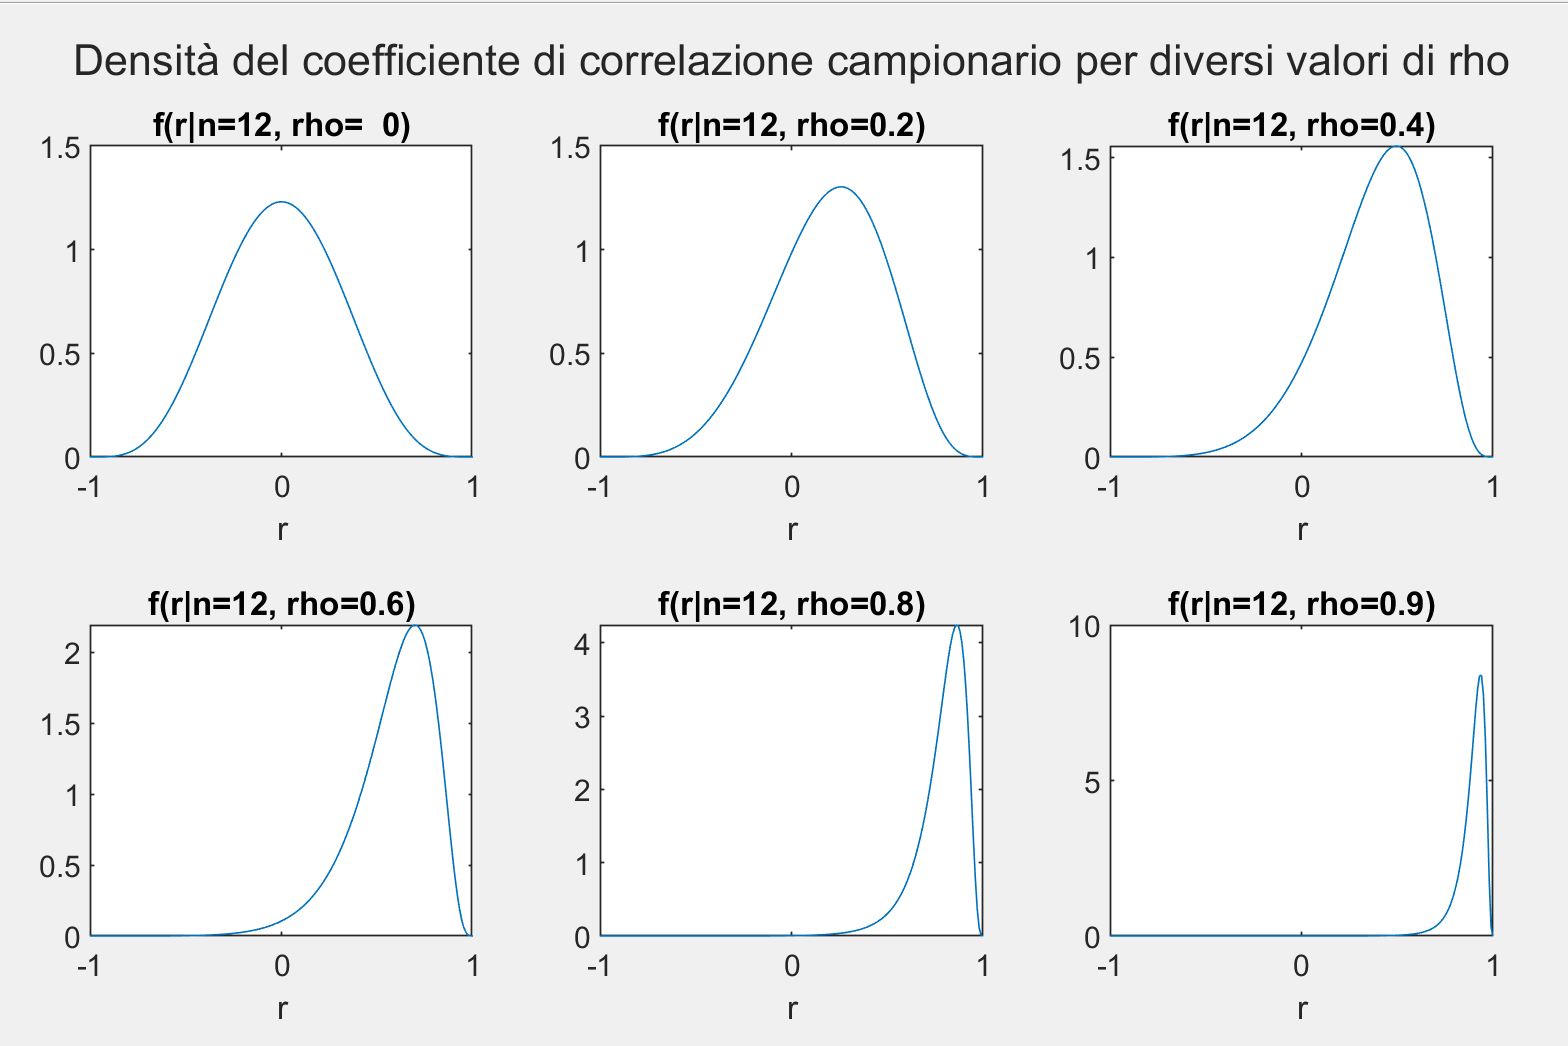

## 6) I gradi o ranghi

La matrice di seguito contiene i voti ottenuti nell'esame di matematica generale (MAT) e nell'esame di statistica (STAT) e nell'esame di analisi dei dati per il marketing (ADM) di 20 studenti. 

MAT STAT ADM

    21    29    29

    24    23    29

    22    26    28

    28    30    29

    27    27    27

    29    28    28

    29    28    28

    28    27    30

    23    20    23

    21    29    26

    25    27    27

    23    20    22

    28    28    24

    22    19    21

    19    20    19

    18    24    22

    18    22    24

    19    18    28

    29    30    30

    23    26    19

Costruire la matrice dei ranghi.  A ciascuno dei posti a pari merito assegnare un grado uguale alla media aritmetica dei gradi che essi avrebbero avuto se distinguibili.  Costruire la table che coniene i ranghi come mostrato nell'immagine che segue (anteprima output dele prime 8 righe). 

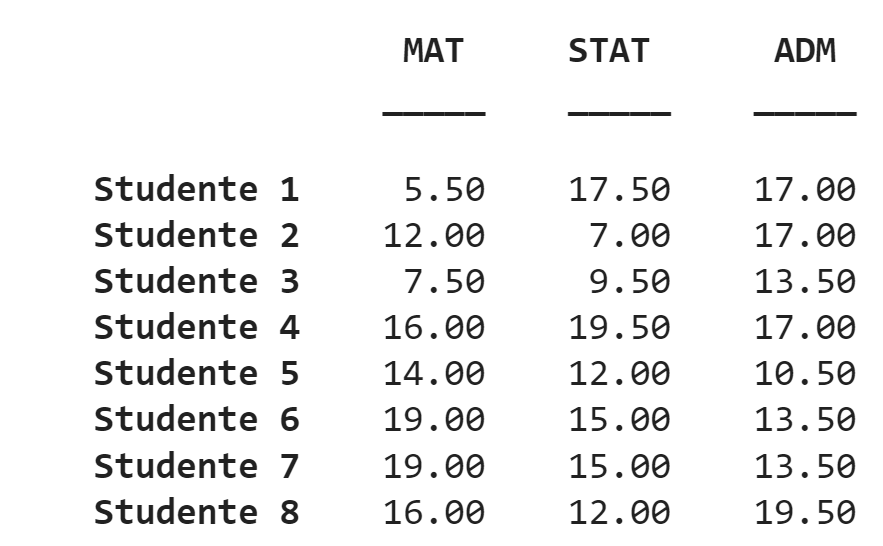

Calcolare la matrice dei coefficienti di cograduzione e verificare la significatività delle relazioni lineari sui gradi (o posti d'ordine). Commentare i p-values della matrice di cograduazione. Verificare l'uguaglianza tra le correlazioni calcolate sui ranghi e i coefficienti di cograduazione calcolati direttamente sulla matrice originaria dei voti.